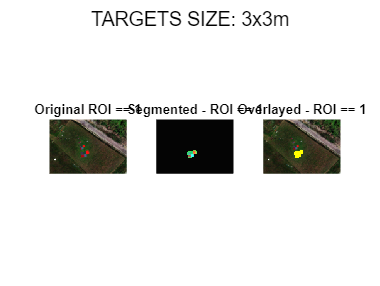

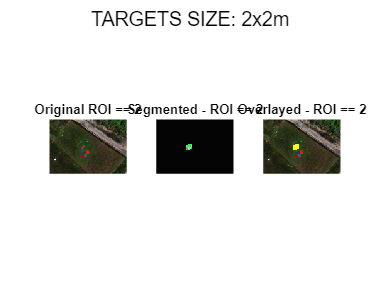

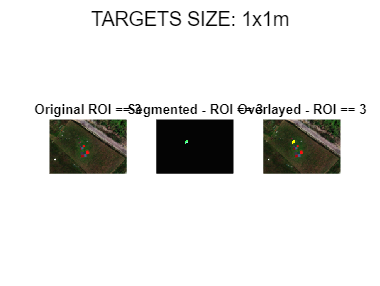

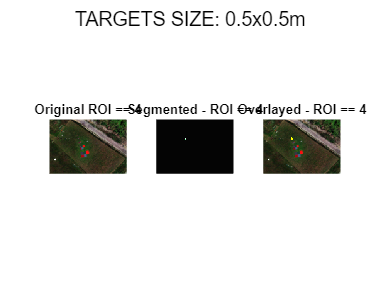

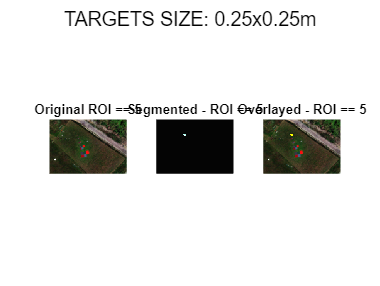

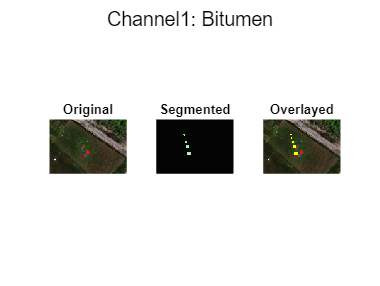

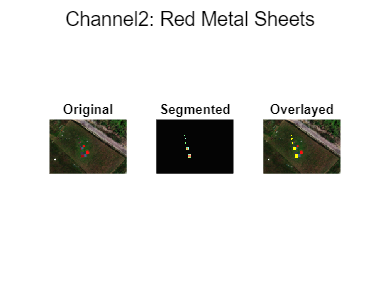

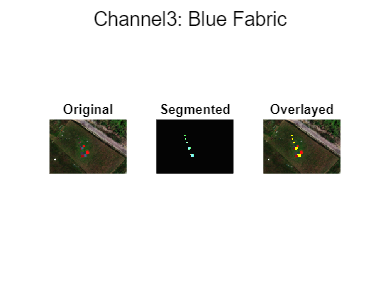

% TARGETS DETECTION
TargetsDetection()

ans = 6×2 table
    Column of sig    Endmember Class Name
    _____________    ____________________

          1          {'Bitumen'         }
          2          {'Red Metal Sheets'}
          3          {'Blue Fabric'     }
          4          {'Red Fabric'      }
          5          {'Green Fabric'    }
          6          {'Grass'           }


       SET OF COLORS FOR THE PLOT    
                R        G        B  
    _________________________________

    Black         0        0        0
    Red           1        0        0
    Blue          0        0        1
    Purple        1        0        1
    Green         0        1        0
    Orange    0.929    0.694    0.125



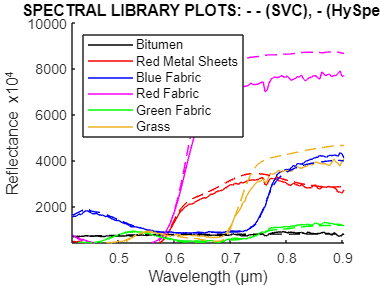

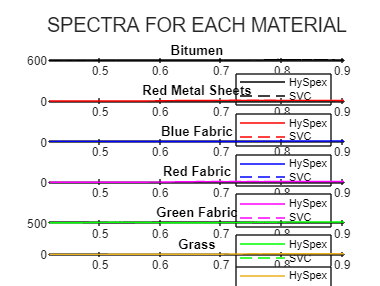

% DLR SPECTRAL LIBRARIES EXTRACTION
[lib_hs, lib_svc, colors, spectraNames] = SpectralLibraries( ...
    'DLR_HySU_HS_library.hdr', ...
    'DLR_HySU_HS_library_ASCII.txt', ...
    'DLR_HySU_SVC_ASCII.txt');

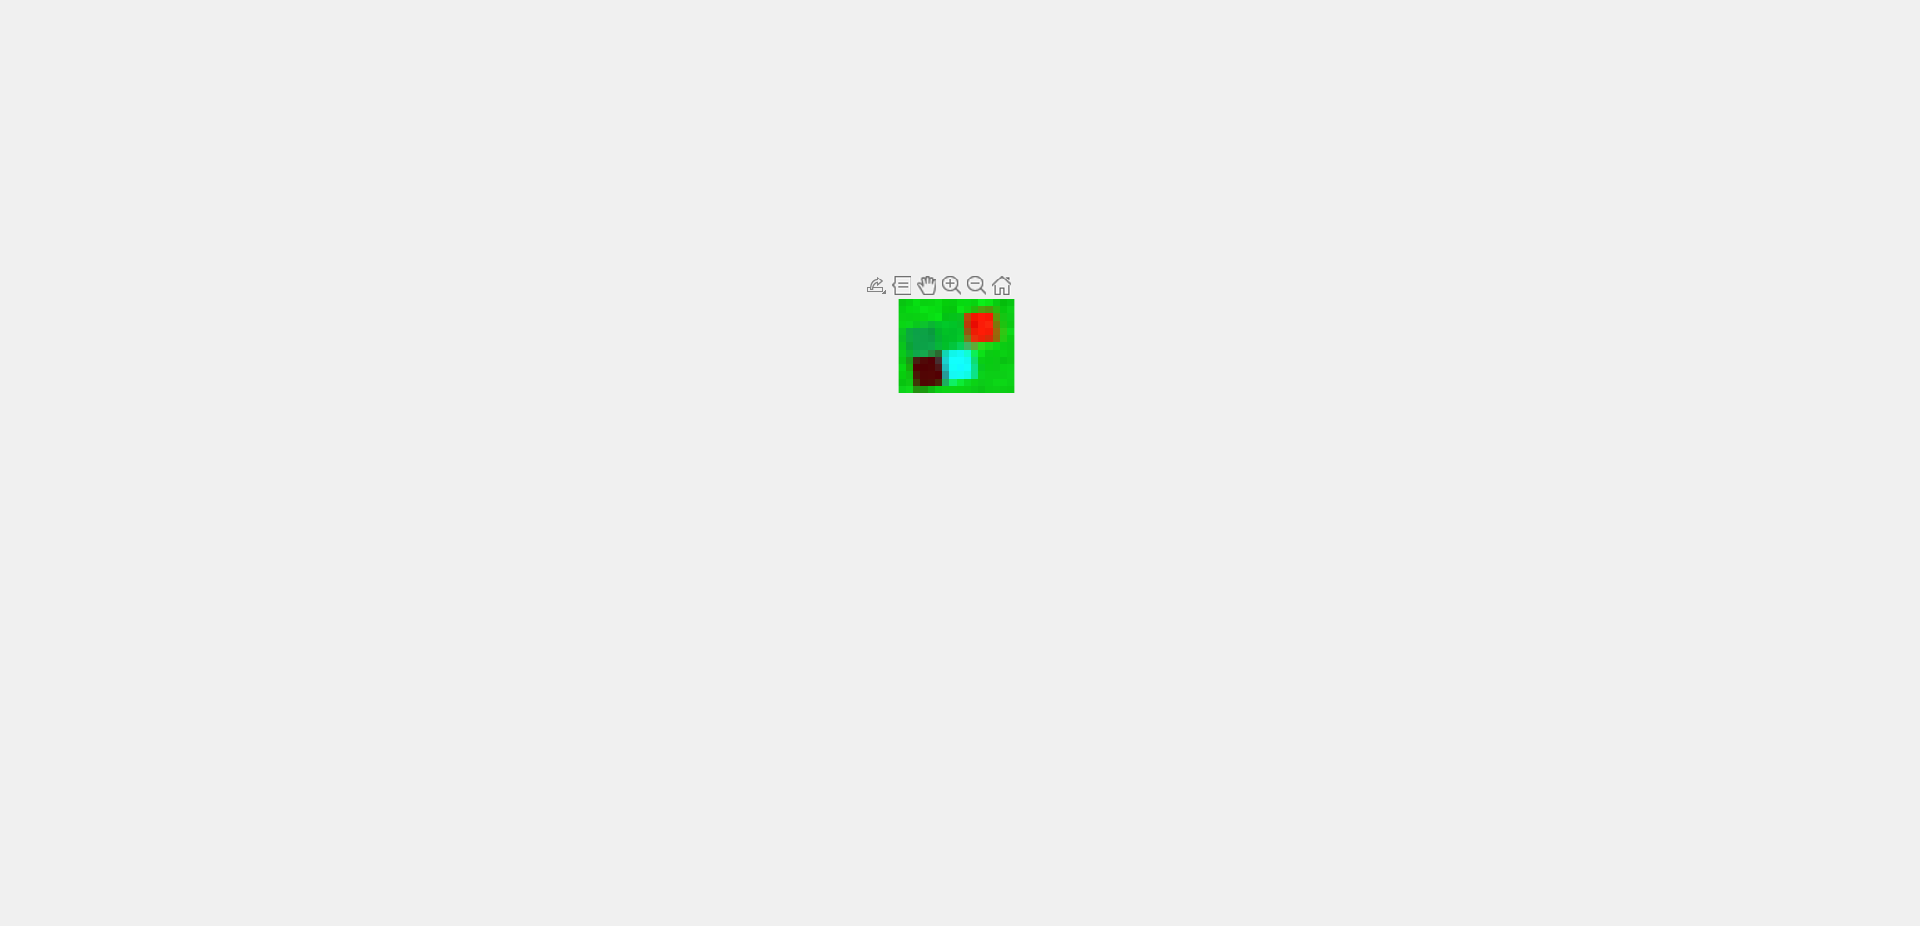

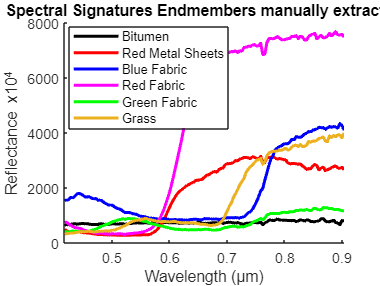

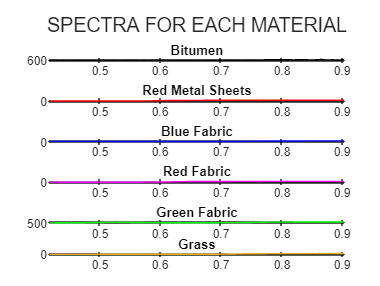

% MANUAL SPECTRAL LIBRARY EXTRACTION (PURE PIXEL CONDITION)

% ATTENTION: WHEN SELECTING THE CENTER PIXEL FOR EACH ENDMEMBER, FOLLOW THE ORDER OF DLR SPECTRAL LIBRARY: 
% (Bitumen, Red Metal Sheets, Blue Fabric, Red Fabric, Green Fabric and Grass)
spectral_library = SpectralSignaturesExtraction('Large.tif','Large.hdr', spectraNames, colors);

signatures = spectral_library(:,2:end);

% UNCOMMENT THIS FOR THE FIRST RUN
filename = 'signatures.mat';
save(filename, 'signatures' )

filename2 = 'spectral_library.mat';
save(filename2, 'spectral_library')

% After a first run of SpectralSignaturesExtraction we can directly load them
% load signatures.mat       
% load spectral_library.mat

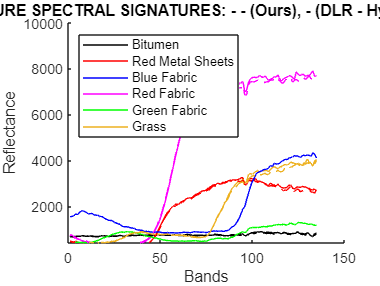

% GROUNDTRUTH COMPARISON (DLR vs Ours)
figure;
hold on;
for i = 1:size(lib_hs, 2)
    plot(lib_hs(:, i), 'Color', colors(i,:));
end  
for i = 1:size(signatures, 2)
    plot(signatures(:, i), '--', 'Color', colors(i, :));
end
title('PURE SPECTRAL SIGNATURES: - - (Ours), - (DLR - HySpex)');
xlabel('Bands');
ylabel('Reflectance');
ylim([400 10000]);
legend(spectraNames, 'Location', 'NorthWest');
hold off

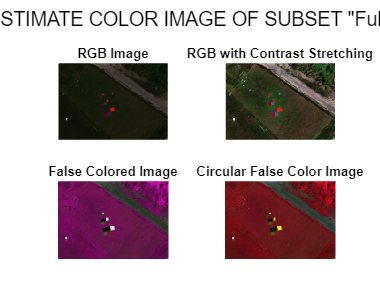

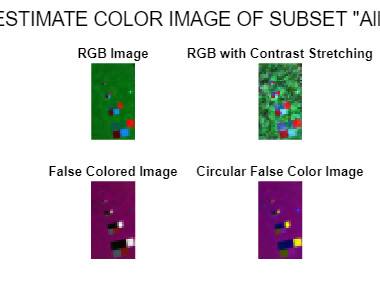

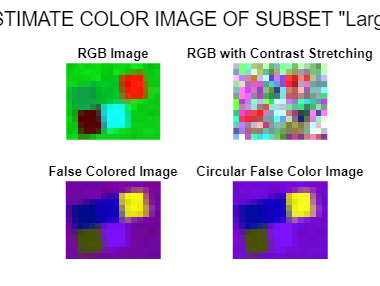

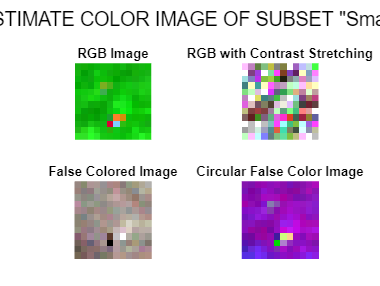

% HCUBES CREATION (Full - All - Large - Small)
file_names = {'Full', 'All', 'Large', 'Small'};
hcube_cell = Hcube(file_names);

hcube_full = hcube_cell{1};
hcube_all = hcube_cell{2};
hcube_large = hcube_cell{3};
hcube_small = hcube_cell{4};

% DIMENSIONALITY ESTIMATION (HFC)
files_tif = {'Full.tif', 'All.tif', 'Large.tif', 'Small.tif'};
files_hdr = {'Full.hdr', 'All.hdr', 'Large.hdr', 'Small.hdr'};

% Users have to select 10^-3 for the standard values
DimensionalityEstimation(files_tif, files_hdr)

     PFA      Full    All    Large    Small
    ______    ____    ___    _____    _____

         1    135     135     135      135 
       0.1      8       7       7        5 
      0.01      6       6       6        2 
     0.001      5       5       5        2 
    0.0001      4       5       4        2 
     1e-05      4       5       4        2 
     1e-06      4       4       4        2 

numEndmembers for PFA=0.00100 and All: 5


ans = 7×5 table
     PFA      Full    All    Large    Small
    ______    ____    ___    _____    _____

         1    135     135     135      135 
       0.1      8       7       7        5 
      0.01      6       6       6        2 
     0.001      5       5       5        2 
    0.0001      4       5       4        2 
     1e-05      4       5       4        2 
     1e-06      4       4       4        2 


Choose the hypercube to use:
1. hcube_cell{1} of Subfolder Full
2. hcube_cell{2} of Subfolder All
3. hcube_cell{3} of Subfolder Large
4. hcube_cell{4} of Subfolder Small


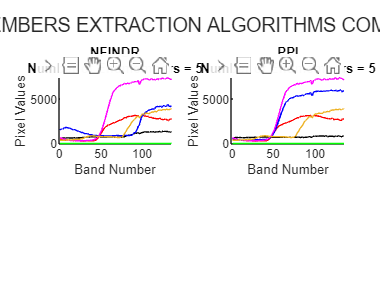

endmembersCell = 1×2 cell array
    {135×6 double}    {135×6 double}


% ENDMEMBERS EXTRACTION (NFINDR - PPI)
endmembersCell = EndmembersExtraction(hcube_cell, numEndmembers_extracted, file_names, spectraNames,colors)

% METRICS ON EXTRACTED SIGNATURES (RMSE - RMSPE) 
% *Only computable if endmembersCell was computed for hcube_all or hcube_large*
Metrics_nfindr = ComputeMetrics(signatures, endmembersCell{1}, spectraNames);

m = 135

n = 6

        SpectraName         RMSE    RMSPE
    ____________________    ____    _____

    {'Bitumen'         }    0.21    55.72
    {'Red Metal Sheets'}    0.01     2.45
    {'Blue Fabric'     }    0.01     4.67
    {'Red Fabric'      }    0.01     2.08
    {'Green Fabric'    }     NaN      NaN
    {'Grass'           }    0.01     3.49



Metrics_ppi = ComputeMetrics(signatures, endmembersCell{2}, spectraNames);

m = 135

n = 6

        SpectraName         RMSE    RMSPE 
    ____________________    ____    ______

    {'Bitumen'         }    0.13      32.7
    {'Red Metal Sheets'}    0.01      2.45
    {'Blue Fabric'     }    0.44    144.22
    {'Red Fabric'      }    0.01      2.08
    {'Green Fabric'    }     NaN       NaN
    {'Grass'           }    0.01      3.49



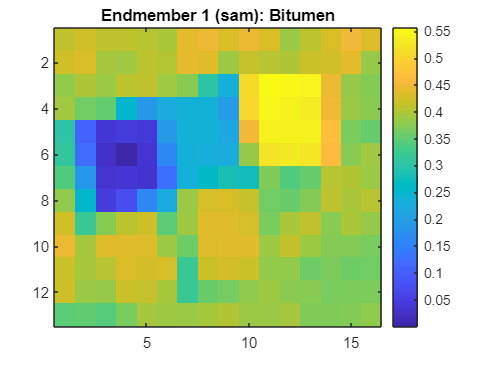

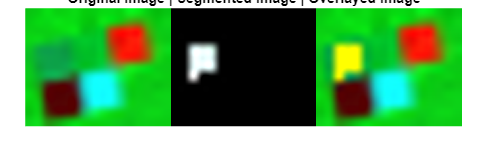

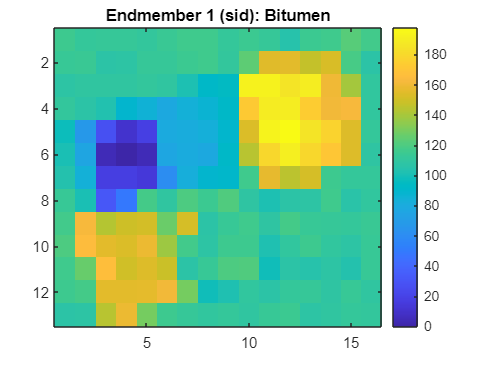

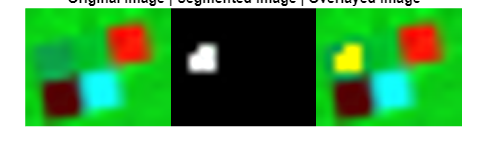

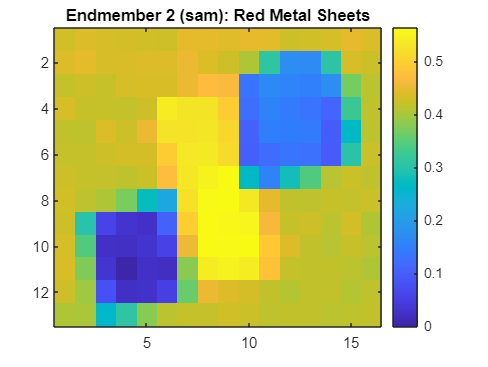

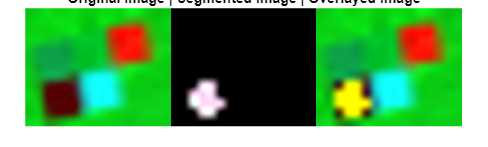

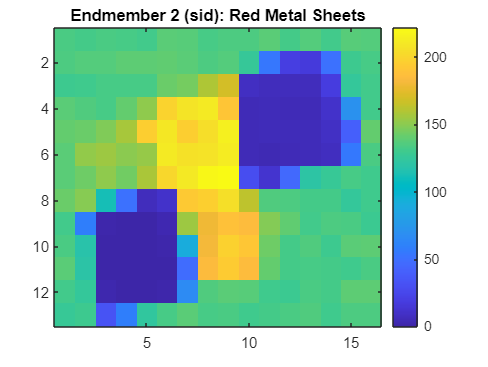

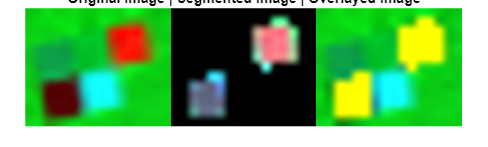

% SPECTRAL MATCHING (SAM - SID)  Try different hcubes
SpectralMatching(hcube_large, spectral_library, spectraNames)

% SpectralMatching(hcube_full, spectral_library,spectraNames)

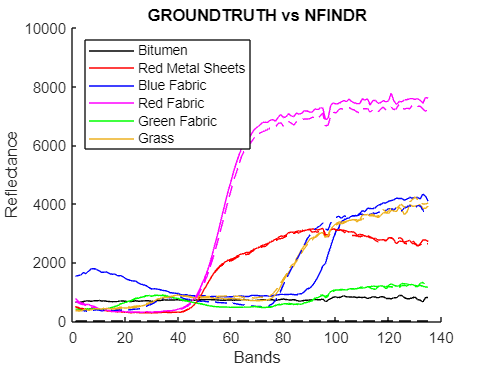

% SPECTRAL COMPARISON (PPI vs Ours)
figure;
hold on;
for i = 1:size(endmembersCell{1}, 2)
    plot(signatures(:, i), 'Color', colors(i,:));
end  
for i = 1:size(endmembersCell{1}, 2)
    plot(endmembersCell{1}(:, i), '--', 'Color', colors(i, :));
end
title('GROUNDTRUTH vs NFINDR');
xlabel('Bands');
ylabel('Reflectance');
ylim([400 10000]);
legend(spectraNames, 'Location', 'NorthWest');
hold off

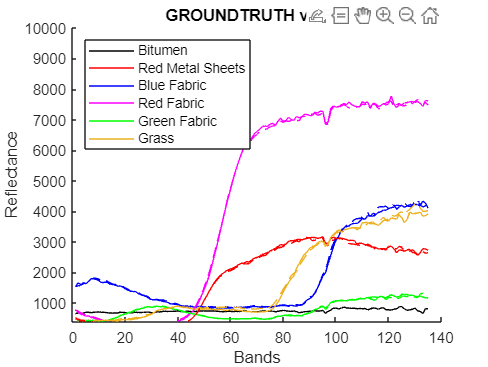

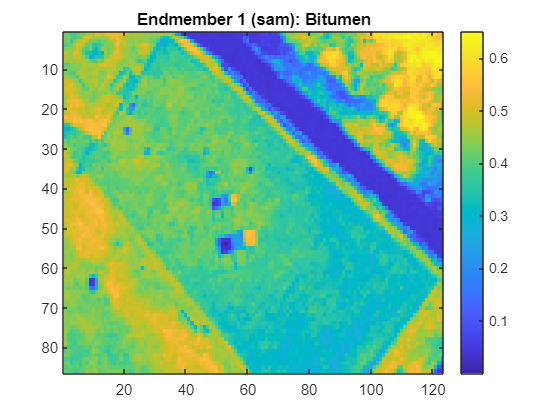

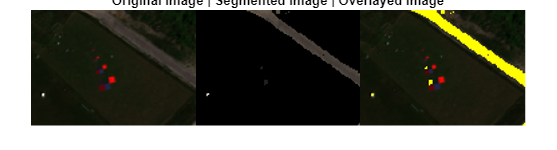

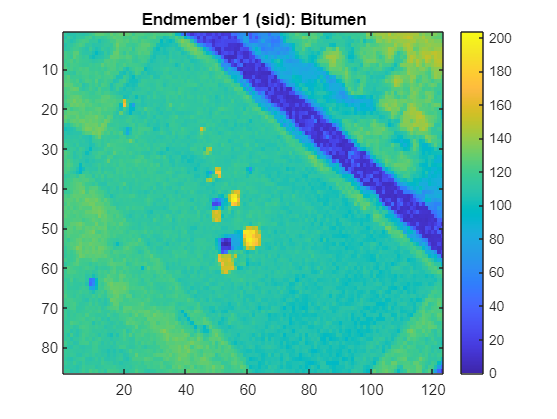

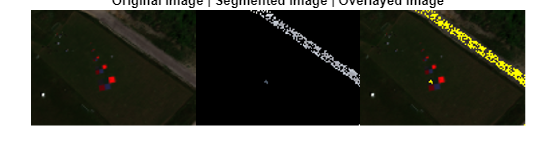

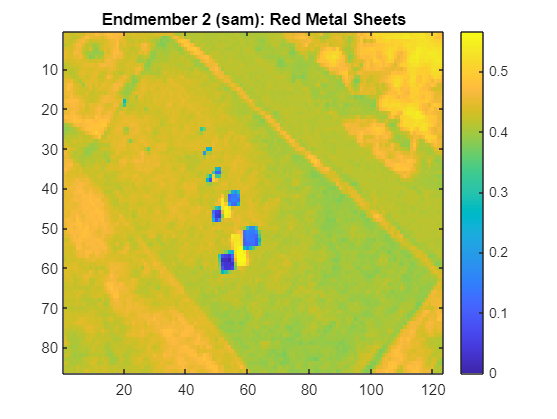

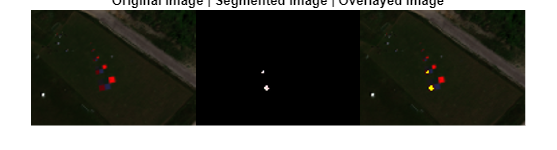

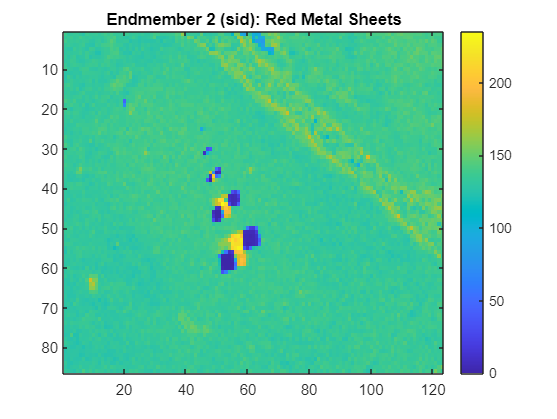


figure;
hold on;
for i = 1:size(endmembersCell{2}, 2)
    plot(signatures(:, i), 'Color', colors(i,:));
end  
for i = 1:size(endmembersCell{2}, 2)
    plot(endmembersCell{2}(:, i), '--', 'Color', colors(i, :));
end
title('GROUNDTRUTH vs PPI');
xlabel('Bands');
ylabel('Reflectance');
ylim([400 10000]);
legend(spectraNames, 'Location', 'NorthWest');
hold off

Choose the hypercube to use:
1. hcube_cell{1} of Subfolder Full
2. hcube_cell{2} of Subfolder All
3. hcube_cell{3} of Subfolder Large
4. hcube_cell{4} of Subfolder Small


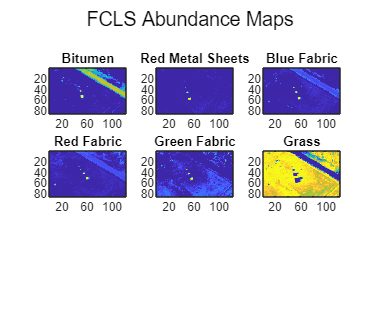

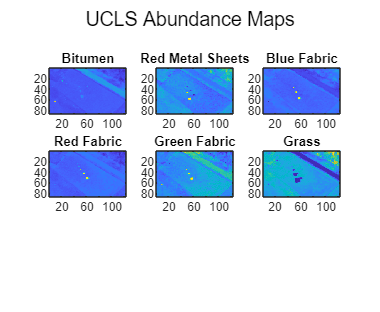

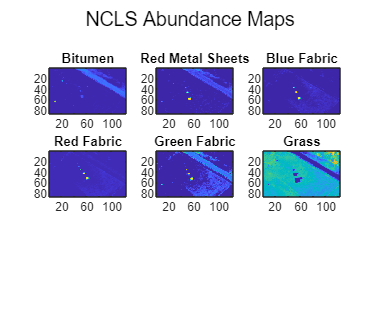

abundance_maps = 3×1 cell array
    {86×123×6 double}
    {86×123×6 double}
    {86×123×6 double}


% ABUNDANCE MAPS (FCLS - UCLS - NCLS)
abundance_maps = AbundanceMaps(hcube_cell, signatures, spectraNames)

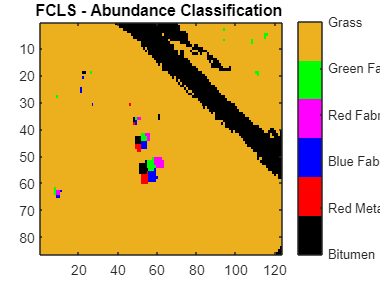

% ABUNDANCE CLASSIFICATION (FCLS - UCLS - NCLS)
% Try with all the subsets!
AbundanceClassifier(abundanceMap_fcls, colors, spectraNames, 5);
title('FCLS - Abundance Classification ')

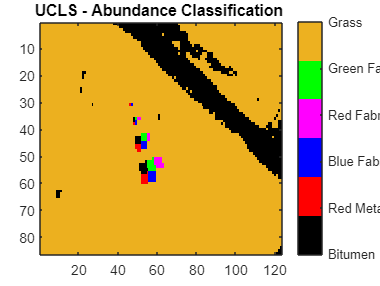


AbundanceClassifier(abundanceMap_ucls, colors, spectraNames, 5);
title('UCLS - Abundance Classification ')

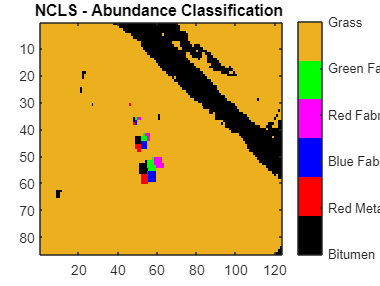


AbundanceClassifier(abundanceMap_ncls, colors, spectraNames, 5);
title('NCLS - Abundance Classification ')